## Plotting

A line plot of two vectors against each other

b2 = 2:0.5:8     %Adding an "increment" specifies the spacing

b2 =     2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000


b3 = linspace(0.4,8.2,10) %linspace creates a vector of regularly spaced numbers, where the beginning, end and length of the vector are specified

b3 =     0.4000    1.2667    2.1333    3.0000    3.8667    4.7333    5.6000    6.4667    7.3333    8.2000


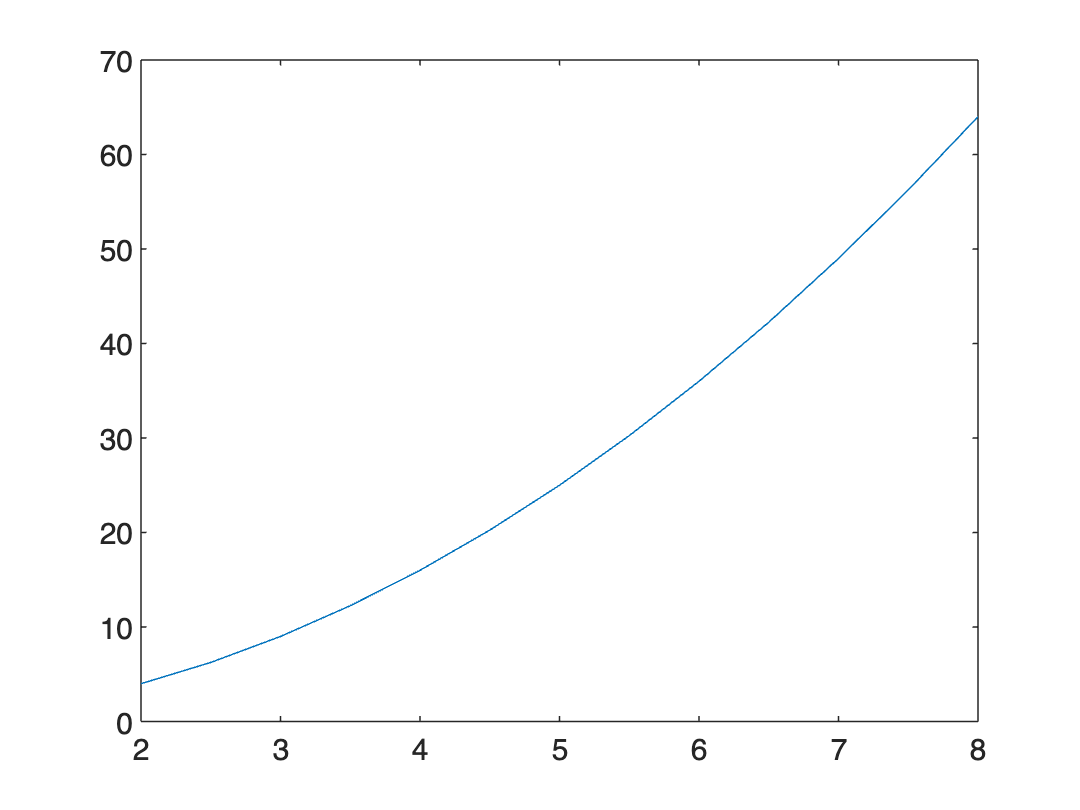

f1 = b2.^2;
plot(b2,f1)

If the second argument in plot is a matrix (with the right size), plot will automatically plot multiple lines

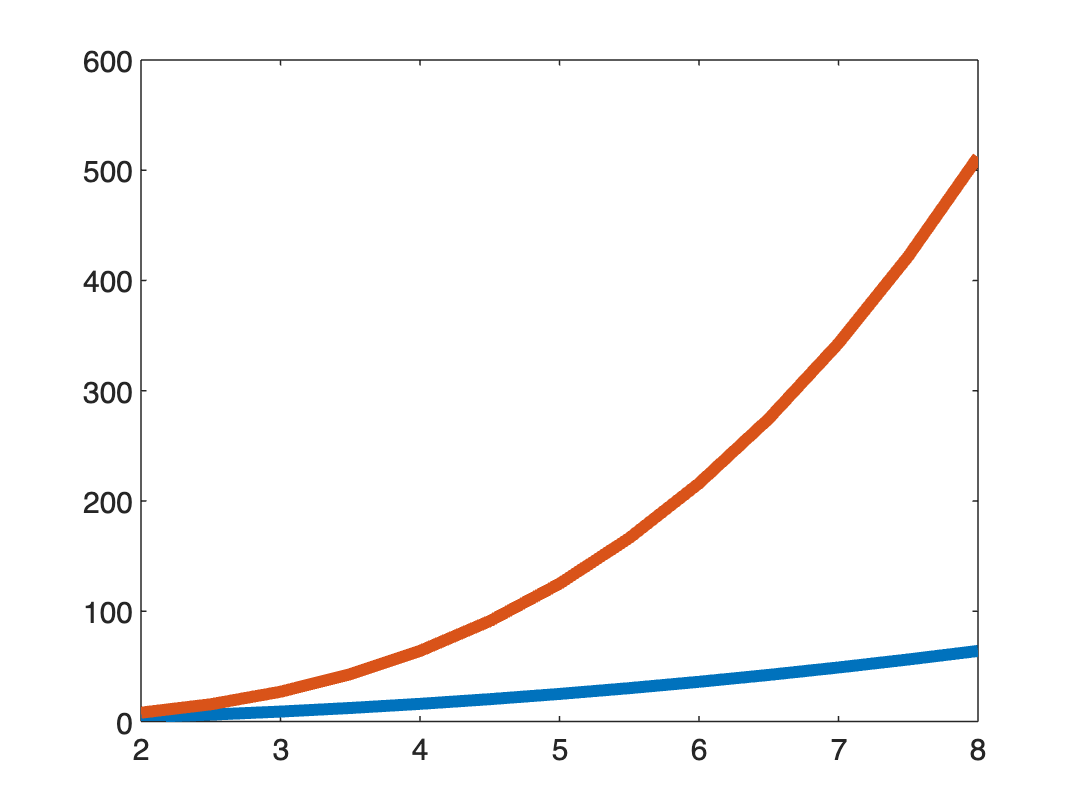

f2 = [b2.^2;b2.^3];
plot(b2,f2,'linewidth',4);  %control width of lines

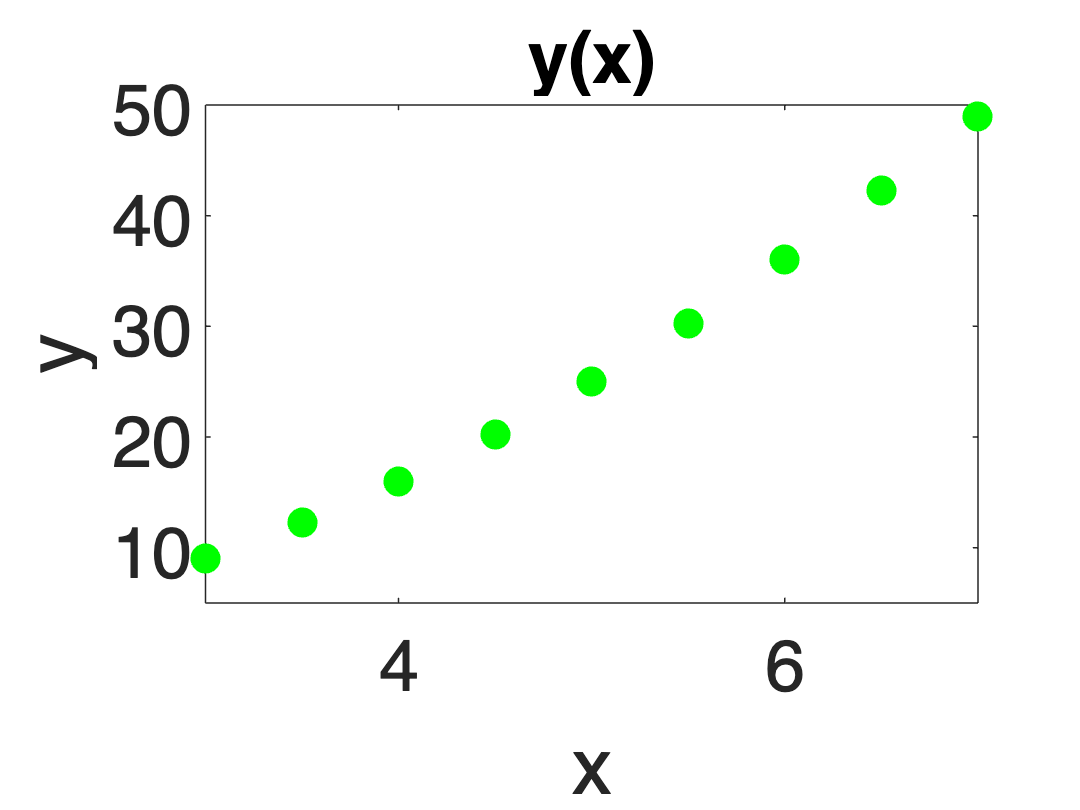

plot(b2,f1,'.','Color','g','markersize',30); %plot inputs as dots, not lines, control color and size of dots
xlabel('x','fontsize',24) %add label to x axis, control font size of label
ylabel('y','fontsize',24) %add label to y axis, control font size of label
set(gca,'fontsize',24) %control text size throughout figure
title('y(x)','fontsize',24) %add title, control font size
xlim([3 7])  %only display part of x-axis
ylim([5 50]) %only display part of y-axis

A contour plot of a 2D field (with X and Y coordinates specified using meshgrid)

[B2,B3] = meshgrid(b2,b3);
F3 = sin(B2) + exp(-(B3-4).^2);
[C,h] = contour(B2,B3,F3) %B2 is the x-axis coordinate, B3, is the y-axis coordinate and F3 is the function being contoured

C =    -0.5000    3.6838    3.6845    3.7215    4.0000    4.2516    4.5000    5.0000    5.1797    5.5000    5.7052    5.7405    5.7412   -0.5000    5.7412    5.7412    5.7385    5.6505    5.5000    5.0000    4.5000    4.0000    3.7790    3.6866    3.6838    3.6838         0    3.1434    3.1440    3.1746    3.5000    3.5211    4.0000    4.5000    5.0000    5.5000    5.8962    6.0000    6.2515    6.2819    6.2825         0    6.2825    6.2825    6.2802    6.2043    6.0000    5.6426    5.5000    5.0000
   12.0000    0.4000    1.2667    2.1333    2.7145    3.0000    3.1546    3.1284    3.0000    2.5828    2.1333    1.2667    0.4000   12.0000    8.2000    7.3333    6.4667    5.6000    5.3807    4.9473    4.9155    5.2930    5.6000    6.4667    7.3333    8.2000   14.0000    0.4000    1.2667    2.1333    2.9561    3.0000    3.5485    3.8598    3.8336    3.4762    3.0000    2.7726    2.1333    1.2667    0.4000   16.0000    8.2000    7.3333    6.4667    5.6000    5.2543    4.7333    4.4690    3

h =   Contour with properties:

    EdgeColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
    FaceColor: 'none'
    LevelList: [-0.5000 0 0.5000 1 1.5000]
        XData: [10×13 double]
        YData: [10×13 double]
        ZData: [10×13 double]

  Show all properties


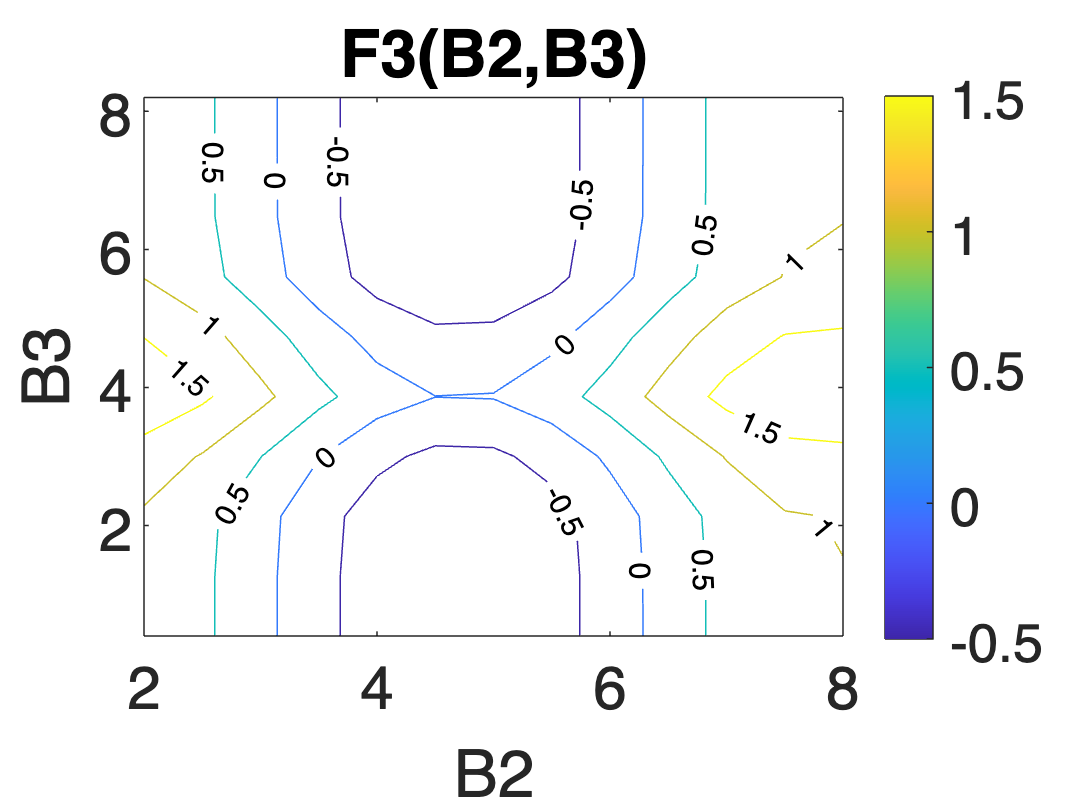

colorbar          %add a colorbar for the contours
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)
clabel(C,h)

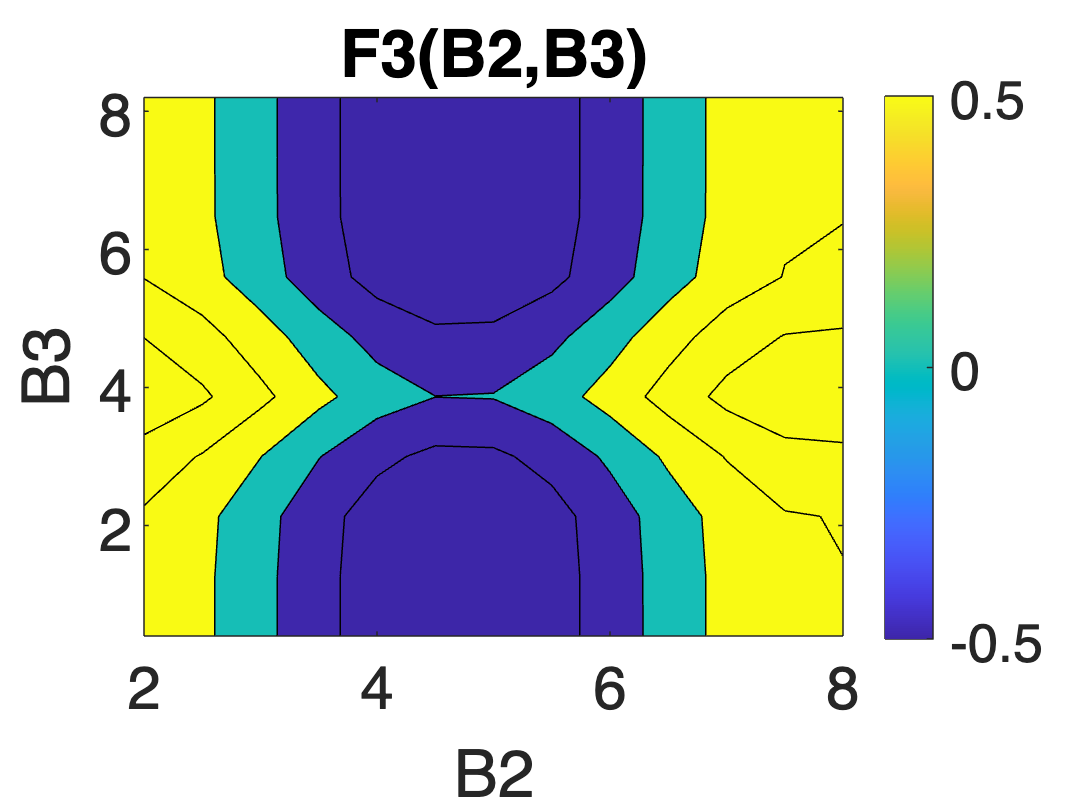

contourf(B2,B3,F3) %filled contour plot
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)
caxis([-0.5 0.5]) %specify the range of the colors

A color-gridded plot of a surface (looking top-down) without contour lines

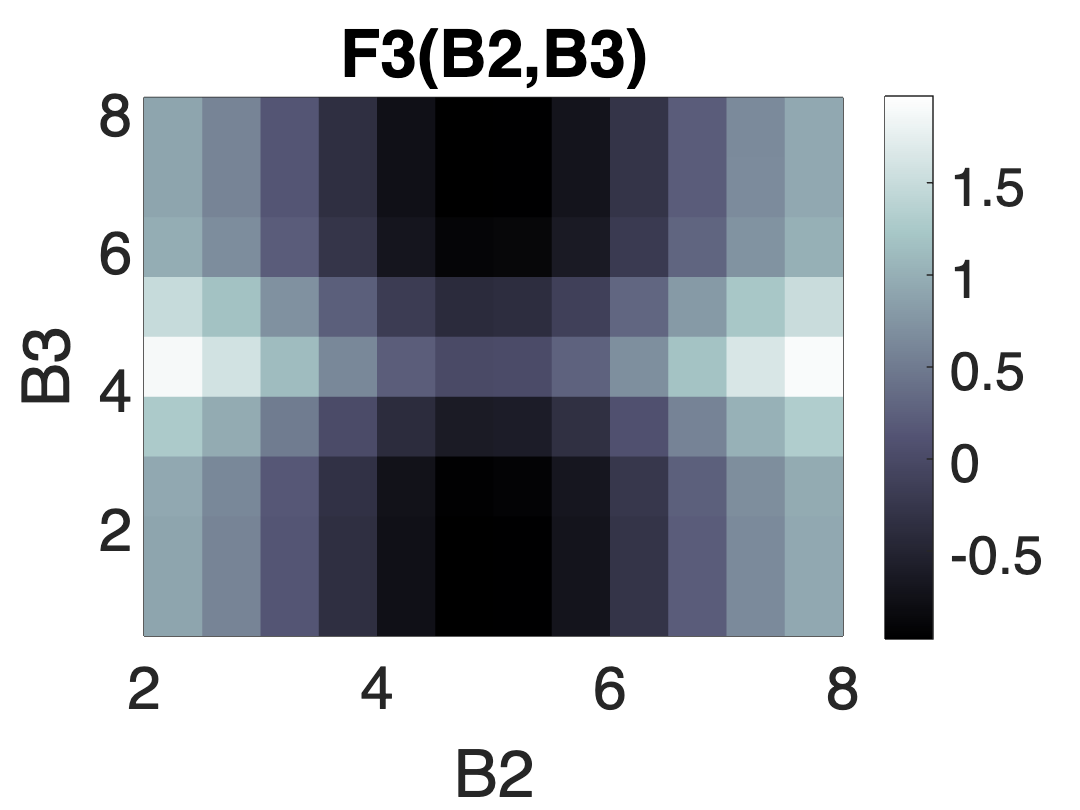

pcolor(B2,B3,F3) %filled contour plot
shading('flat')  %do not interpolate between grid boxes
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)
colormap('bone') %specify the colormap (see built in colormaps in MATLAB or download colorbrewer or cmocean)

A note on colormaps: the type of colormap you use depends on what you are trying to convey about the data. There are generally three types of colormaps

    1. Sequential: Continuous gradient between two color end members - useful for conveying magnitude or range of data between two interesting values

    2. Diverging: Continuous gradient from one intermediate color to two different end members (so three colors) - useful for conveying variations from a single important value (often zero)

    3. Qualitative: Many different colors either with some gradient in between or as a way of conveying discrete (i.e. no continuously valued) data

pcolor(B2,B3,F3) %filled contour plot
shading('flat')  %do not interpolate between grid boxes
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)

colormap(brewermap([],'RdBu')); % preselect the colorscheme.

Unrecognized function or variable 'brewermap'.

caxis([-1 1])

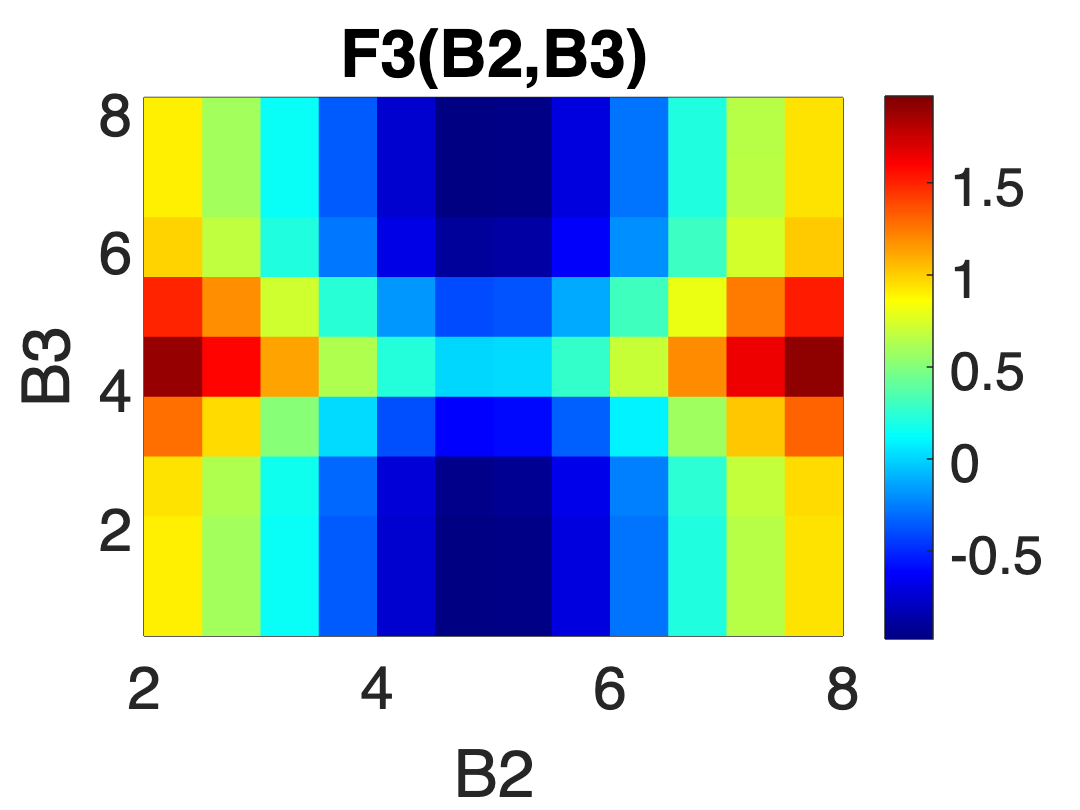

pcolor(B2,B3,F3) %filled contour plot
shading('flat')  %do not interpolate between grid boxes
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)
colormap('jet'); % preselect the colorscheme.

A 3D plot (with perspective) of a surface

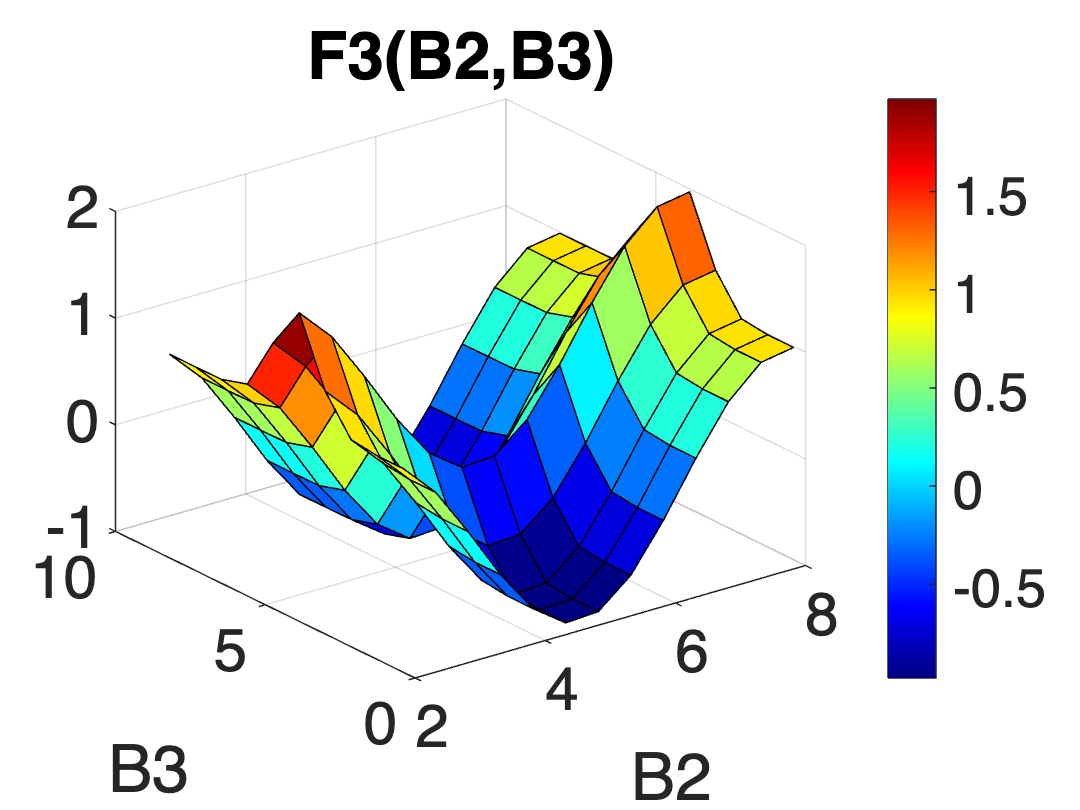

surf(B2,B3,F3) %
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)

Now lets make a matrix of random numbers that is a bit more "data" like

X = 0.3*randn(10,13) + F3;

We can make a histogram of all the "data" specifying to split the data into 10 bins

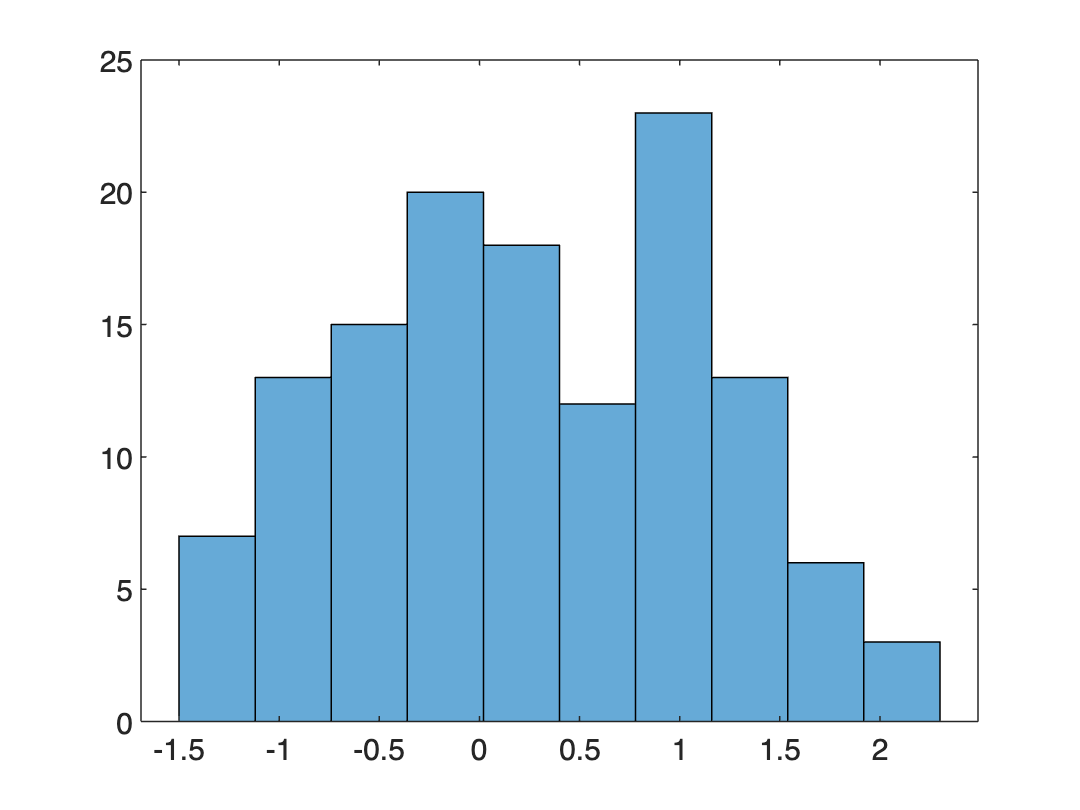

histogram(X(:),10) %the : unwraps a matrix into a vector

We can also extract the histogram data into vectors and then plot them in other ways

[NX, EDGES] = histcounts(X(:),10)

NX =      7    13    15    20    18    12    23    13     6     3


EDGES =    -1.5000   -1.1200   -0.7400   -0.3600    0.0200    0.4000    0.7800    1.1600    1.5400    1.9200    2.3000


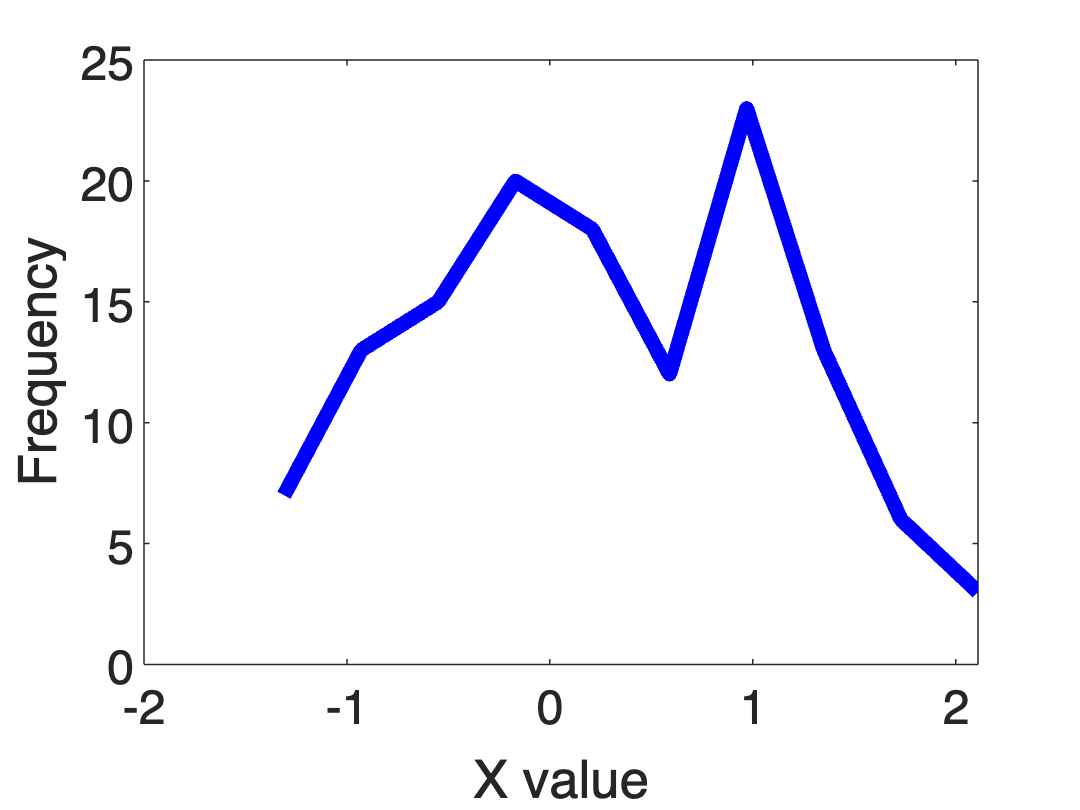

plot((EDGES(1:end-1)+EDGES(2:end))./2,NX,'b','linewidth',5)
xlabel('X value','fontsize',16)
ylabel('Frequency','fontsize',16)
set(gca,'fontsize',16)

A box plot is another useful way to visual data which displays the median (center), 25/75 percentiles (box edges), range of dataset (all non-outliers) defined in some way (in MATLAB default is range up to 1.5*IQR) as "whiskers" and any outliers beyond that (+)

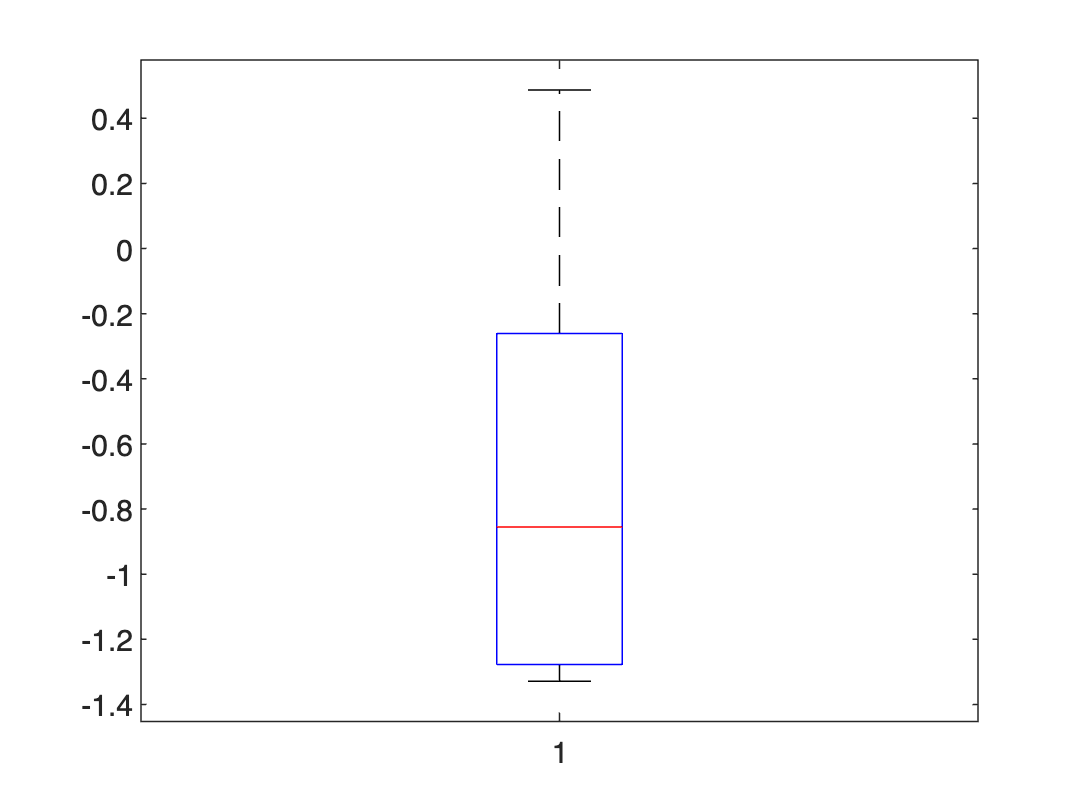

boxplot(X(:,7))

If a matrix is provided, each column is plotted as a separate box plot

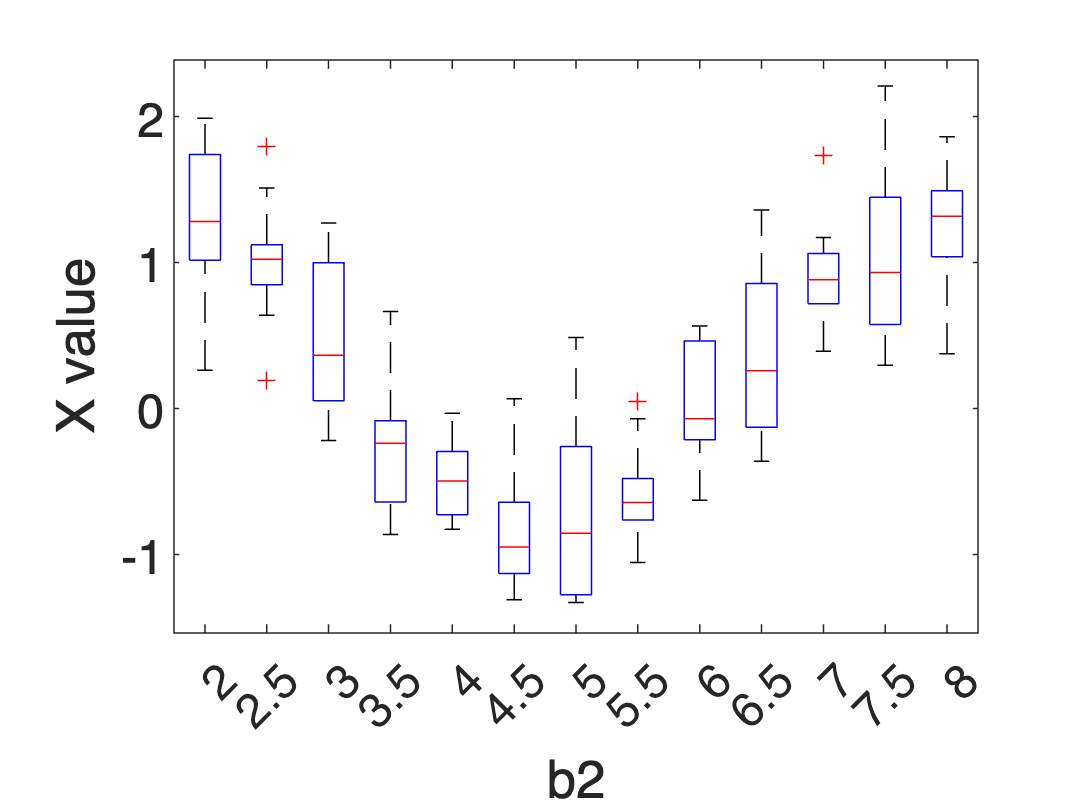

boxplot(X,b2)
xlabel('b2','fontsize',16)
ylabel('X value','fontsize',16)
set(gca,'fontsize',16)

Subplot allows you to put many different axes in the same figure. They are arranged in a grid defined by the subplot command: subplot(x,y,z) where x,y define the grid of axes and z tells MATLAB which axis to plot on. Subplot should be called before each plotting command

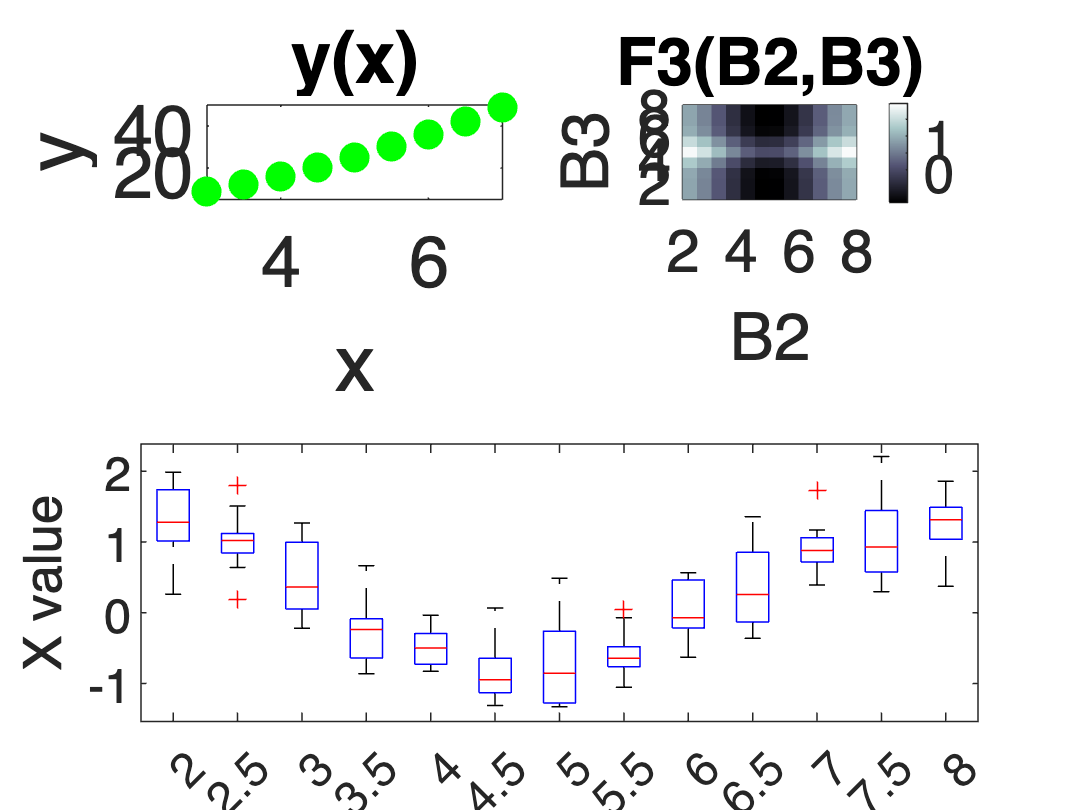

subplot(2,2,1)
plot(b2,f1,'.','Color','g','markersize',30); %plot inputs as dots, not lines, control color and size of dots
xlabel('x','fontsize',24) %add label to x axis, control font size of label
ylabel('y','fontsize',24) %add label to y axis, control font size of label
set(gca,'fontsize',24) %control text size throughout figure
title('y(x)','fontsize',24) %add title, control font size
xlim([3 7])  %only display part of x-axis
ylim([5 50]) %only display part of y-axis

subplot(2,2,2)
pcolor(B2,B3,F3) %filled contour plot
shading('flat')  %do not interpolate between grid boxes
colorbar         
xlabel('B2','fontsize',20)
ylabel('B3','fontsize',20)
title('F3(B2,B3)','fontsize',20)
set(gca,'fontsize',20)
colormap('bone')

subplot(2,2,3:4)
boxplot(X,b2)
xlabel('b2','fontsize',16)
ylabel('X value','fontsize',16)
set(gca,'fontsize',16)